% connectivity values come from import values in CONN, you can find them in
% set up->second level covariates. for details see HOWTO_connectivity_and_behavior_correlations.docx 

addpath /Users/k.siudakrzywicka/Desktop/RDS_fMRI/RDS_localizers/scripts
cd /Users/k.siudakrzywicka/Desktop/RDS_fMRI/Controls/color_rs_connectivity/behavioral_corelates

%locate subject numbers
subs = dir('/Users/k.siudakrzywicka/Desktop/RDS_fMRI/Controls/Processed_566_471_vol');
subs = {subs.name};
subs = cellfun(@str2double,subs(4:end));
subs = subs-1000;
subs = subs(1:end-6); %take out aditional 6 women

naming_categ = readtable('color_categorization_naming_2ndBlock.xlsx');
partial = naming_categ{:, [2,3]};

behavior = naming_categ{:,7 };

connectivity = [-0.0437327 0.204121 0.214168 0.144569 0.0979717 0.143297 0.256646 -0.0461484 0.137161 -0.32824 -0.059902 0.16525 0.134405 0.0968771 -0.0139668 NaN -0.0364638 0.0962955 0.148974 NaN;
    -0.102643 0.126645 0.303922 0.118971 0.184869 0.124062 0.249373 -0.0807016 0.269338 -0.281279 -0.0281272 -0.000114652 0.0118272 0.107977 -0.0376007 NaN -0.0250033 0.214788 0.170565 NaN]';
% connectivity values come from import values in CONN, you can find them in
% set up->second level covariates. for details see HOWTO_connectivity_and_behavior_correlations.docx 

for_reg = [partial,behavior,connectivity];



reg_aMTG = array2table(for_reg(:,1:end-1), 'VariableNames', {'Gender', 'Age', 'RT', 'Connectivity'});
reg_aMTG_model = fitlm(reg_aMTG,'Connectivity~Gender+Age+RT')

reg_aMTG_model = Linear regression model:
    Connectivity ~ 1 + Gender + Age + RT

Estimated Coefficients:
                   Estimate        SE         tStat       pValue 
                   _________    _________    ________    ________

    (Intercept)     -0.27755      0.38713    -0.71694      0.4852
    Gender         -0.052621      0.12353    -0.42598      0.6766
    Age            0.0082892    0.0072784      1.1389     0.27387
    RT              -0.55069      0.22082     -2.4939    0.025769


Number of observations: 18, Error degrees of freedom: 14
Root Mean Squared Error: 0.125
R-squared: 0.337,  Adjusted R-Squared 0.195
F-statistic vs. constant model: 2.37, p-value = 0.114

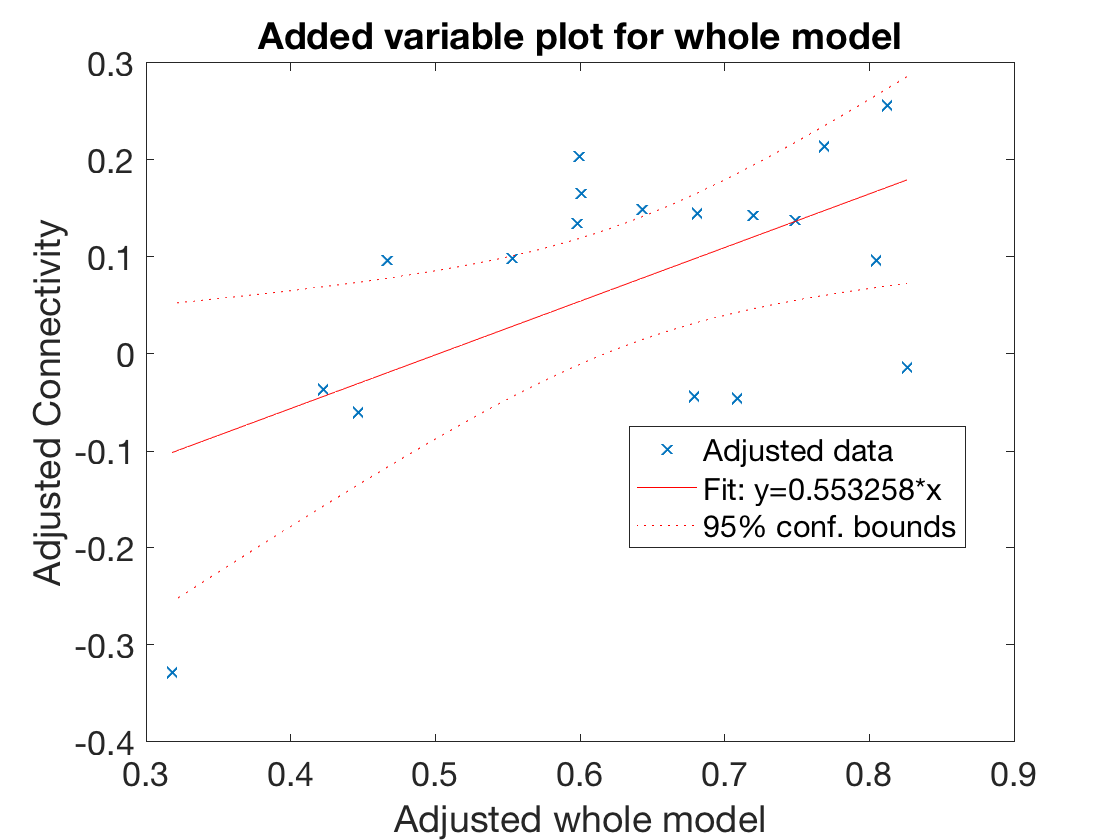

plot(reg_aMTG_model)

h1 =   2×1 Line array:

  Line    (data)
  Line    (fit)


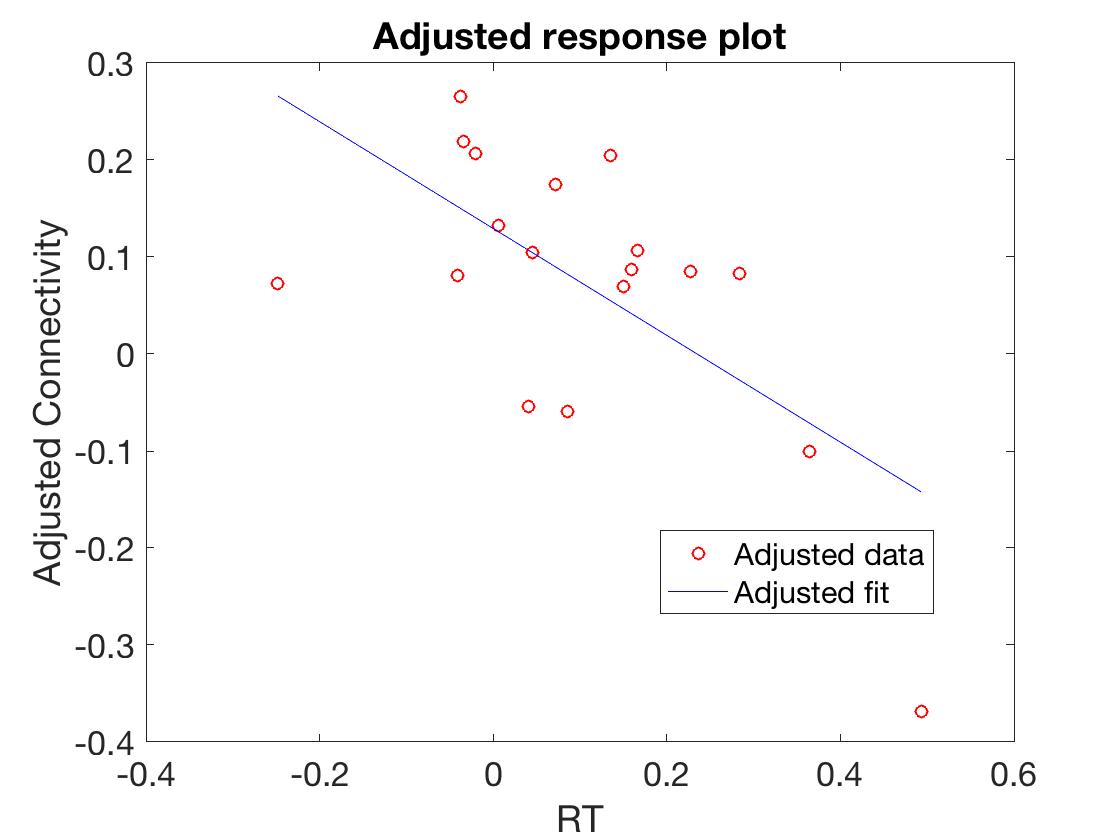

h1 = plotAdjustedResponse(reg_aMTG_model,'RT')

reg_pMTG = array2table(for_reg(:,[1:3,end]), 'VariableNames', {'Gender', 'Age', 'RT', 'Connectivity'});
reg_pMTG_model = fitlm(reg_pMTG,'Connectivity~Gender+Age+RT')

reg_pMTG_model = Linear regression model:
    Connectivity ~ 1 + Gender + Age + RT

Estimated Coefficients:
                   Estimate        SE         tStat       pValue 
                   _________    _________    ________    ________

    (Intercept)      0.10555      0.44239     0.23859     0.81488
    Gender           -0.1125      0.14116    -0.79693      0.4388
    Age            0.0010423    0.0083174     0.12531     0.90206
    RT              -0.57949      0.25234     -2.2965    0.037601


Number of observations: 18, Error degrees of freedom: 14
Root Mean Squared Error: 0.143
R-squared: 0.275,  Adjusted R-Squared 0.12
F-statistic vs. constant model: 1.77, p-value = 0.199

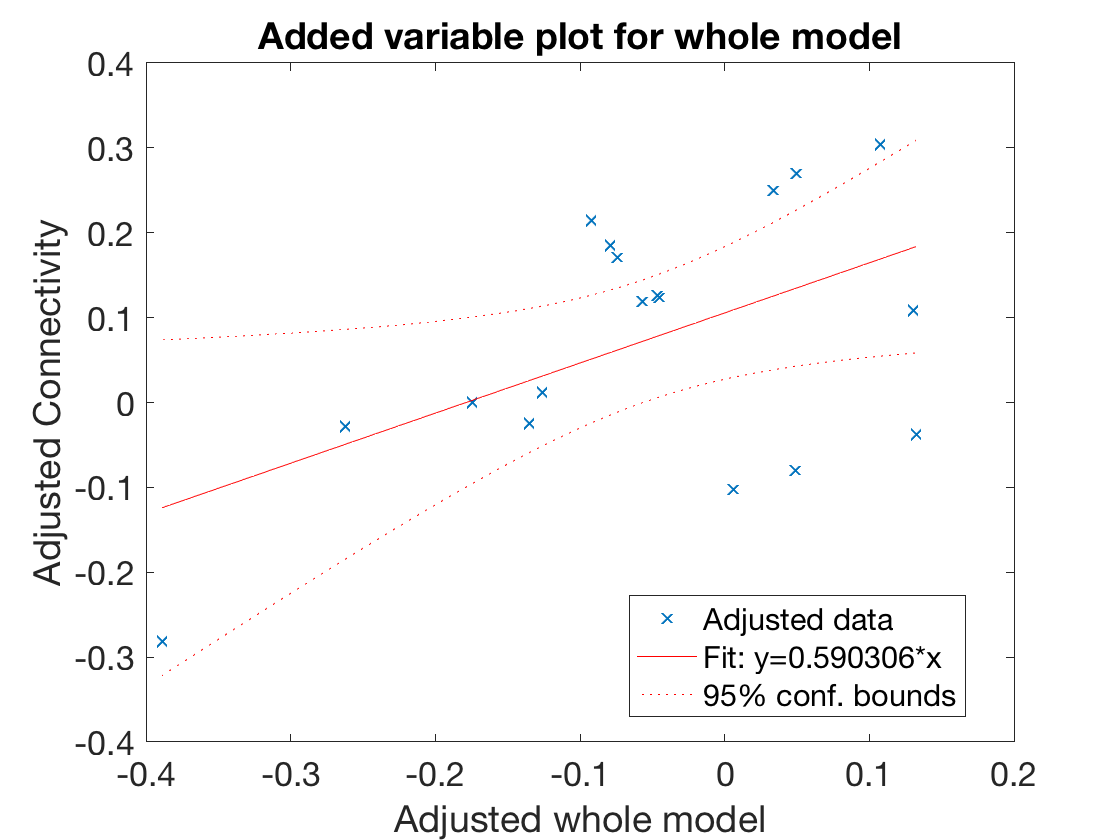

plot(reg_pMTG_model)

h2 =   2×1 Line array:

  Line    (data)
  Line    (fit)


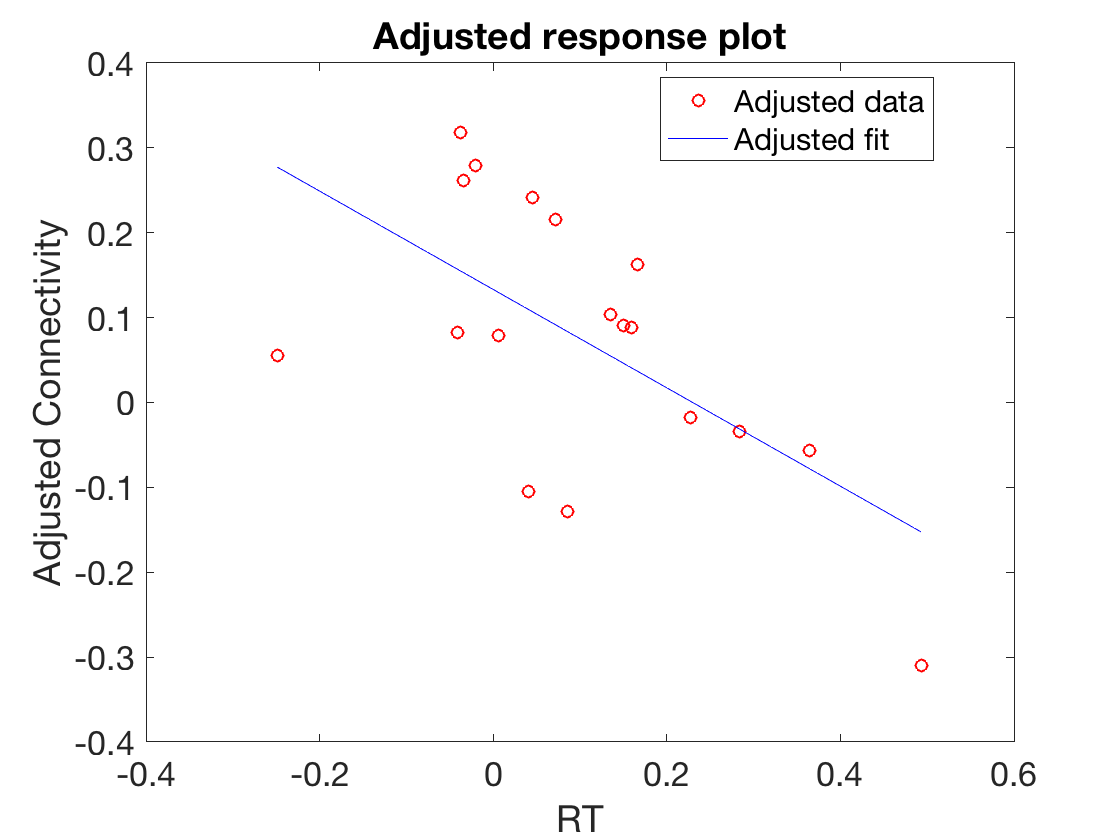

h2 = plotAdjustedResponse(reg_pMTG_model,'RT')

ROI rom RDS's analysis

PCC_RDS_ROI = [0.0746116 0.132856 0.213245 0.111323 0.231646 0.148588 0.230983 0.131317 0.225872 -0.375882 -0.0863032 0.0881594 0.188548 0.129274 -0.133069 NaN -0.0739008 0.0586843 0.136695 NaN];
PCC_RDS_ROI = array2table([partial,behavior,PCC_RDS_ROI'] , 'VariableNames', {'Gender', 'Age', 'RT', 'Connectivity'});
PCC_RDS_ROI_model = fitlm(PCC_RDS_ROI,'Connectivity~Gender+Age+RT')

PCC_RDS_ROI_model = Linear regression model:
    Connectivity ~ 1 + Gender + Age + RT

Estimated Coefficients:
                   Estimate        SE         tStat      pValue  
                   _________    _________    _______    _________

    (Intercept)      0.12699      0.39831    0.31882      0.75457
    Gender          -0.24578       0.1271    -1.9337     0.073622
    Age            0.0015354    0.0074887    0.20503       0.8405
    RT              -0.68518       0.2272    -3.0158    0.0092569


Number of observations: 18, Error degrees of freedom: 14
Root Mean Squared Error: 0.129
R-squared: 0.445,  Adjusted R-Squared 0.326
F-statistic vs. constant model: 3.74, p-value = 0.0364

h3 =   2×1 Line array:

  Line    (data)
  Line    (fit)


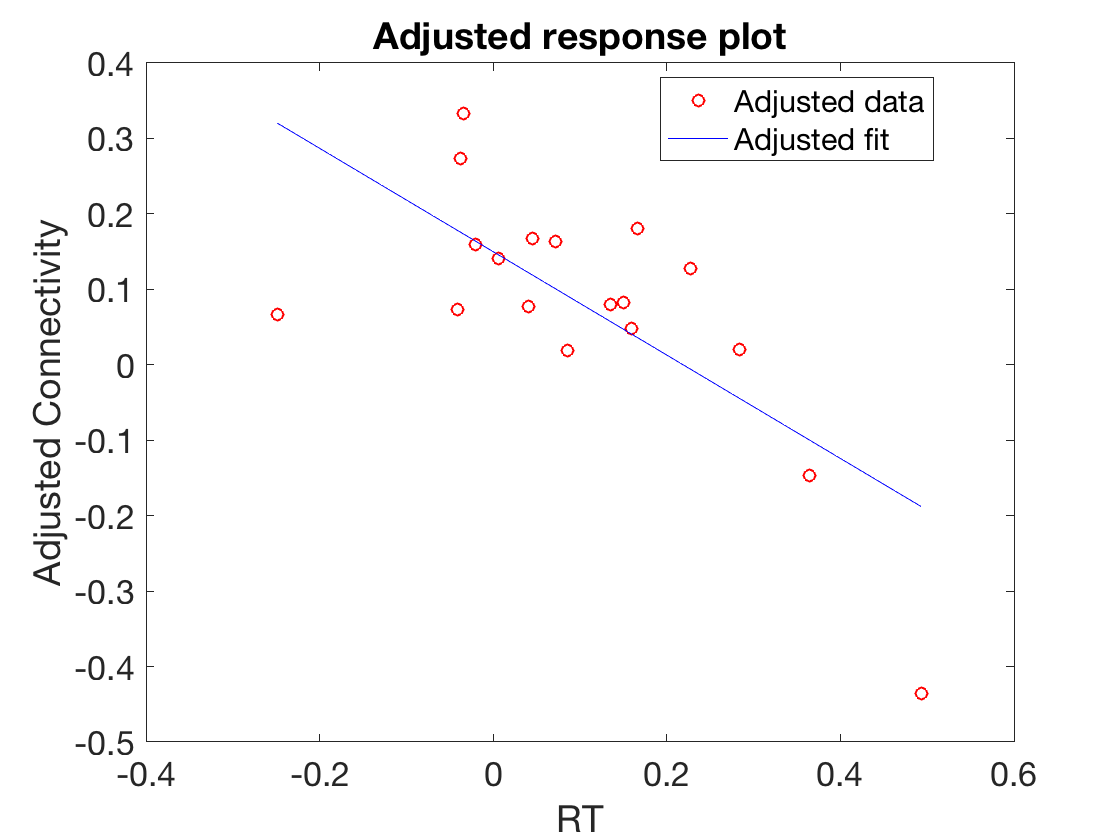

h3 = plotAdjustedResponse(PCC_RDS_ROI_model,'RT')

Similar analysis for specificity (is it only PCC or othe domain region also show this connectivity pattern?)

VWFA_pMTG = [-0.0193152 0.056352 -0.0193091 -0.00963124 0.311898 0.161472 -0.0617169 0.083871 -0.0279307 0.00186289 -0.115217 0.112901 0.270371 -0.0376636 -0.208305 NaN 0.08725 -0.233355 0.0924544 NaN]

VWFA_pMTG =    -0.0193    0.0564   -0.0193   -0.0096    0.3119    0.1615   -0.0617    0.0839   -0.0279    0.0019   -0.1152    0.1129    0.2704   -0.0377   -0.2083       NaN    0.0872   -0.2334    0.0925       NaN



VWFA_pMTG = array2table([partial,behavior,VWFA_pMTG'] , 'VariableNames', {'Gender', 'Age', 'RT', 'Connectivity'});
VWFA_pMTG_model = fitlm(VWFA_pMTG,'Connectivity~Gender+Age+RT')

VWFA_pMTG_model = Linear regression model:
    Connectivity ~ 1 + Gender + Age + RT

Estimated Coefficients:
                    Estimate        SE         tStat      pValue 
                   __________    _________    ________    _______

    (Intercept)      0.086517      0.44421     0.19476    0.84838
    Gender           -0.08735      0.14174    -0.61625    0.54762
    Age            -0.0012266    0.0083516    -0.14687    0.88533
    RT                0.19111      0.25338     0.75425     0.4632


Number of observations: 18, Error degrees of freedom: 14
Root Mean Squared Error: 0.144
R-squared: 0.157,  Adjusted R-Squared -0.0239
F-statistic vs. constant model: 0.868, p-value = 0.481



VWFA_aMTG = [0.00985526 0.109287 -0.0956005 0.164656 0.291632 -0.0173411 0.00994892 0.182427 0.0536675 0.0166333 -0.124239 0.0269214 0.0977342 -0.0545523 -0.186126 NaN 0.0899484 -0.356432 0.0897821 NaN]

VWFA_aMTG =     0.0099    0.1093   -0.0956    0.1647    0.2916   -0.0173    0.0099    0.1824    0.0537    0.0166   -0.1242    0.0269    0.0977   -0.0546   -0.1861       NaN    0.0899   -0.3564    0.0898       NaN



VWFA_aMTG = array2table([partial,behavior,VWFA_aMTG'] , 'VariableNames', {'Gender', 'Age', 'RT', 'Connectivity'});
VWFA_aMTG_model = fitlm(VWFA_aMTG,'Connectivity~Gender+Age+RT')

VWFA_aMTG_model = Linear regression model:
    Connectivity ~ 1 + Gender + Age + RT

Estimated Coefficients:
                    Estimate        SE         tStat      pValue 
                   __________    _________    ________    _______

    (Intercept)       0.11924      0.45998     0.25922    0.79924
    Gender           -0.14248      0.14678    -0.97072    0.34816
    Age            -0.0015337    0.0086481    -0.17735    0.86177
    RT               0.068228      0.26237     0.26004    0.79862


Number of observations: 18, Error degrees of freedom: 14
Root Mean Squared Error: 0.149
R-squared: 0.166,  Adjusted R-Squared -0.0123
F-statistic vs. constant model: 0.931, p-value = 0.452




LOC_pMTG =[0.222693 -0.222871 0.28609 -0.0108748 -0.154032 0.141359 -0.0569973 -0.268134 0.332662 -0.036685 0.144858 -0.168866 -0.0667978 0.0918449 0.0154657 NaN 0.145194 -0.0753916 0.123785 NaN]

LOC_pMTG =     0.2227   -0.2229    0.2861   -0.0109   -0.1540    0.1414   -0.0570   -0.2681    0.3327   -0.0367    0.1449   -0.1689   -0.0668    0.0918    0.0155       NaN    0.1452   -0.0754    0.1238       NaN


LOC_pMTG = array2table([partial,behavior,LOC_pMTG'] , 'VariableNames', {'Gender', 'Age', 'RT', 'Connectivity'});
LOC_pMTG_model = fitlm(LOC_pMTG,'Connectivity~Gender+Age+RT')

LOC_pMTG_model = Linear regression model:
    Connectivity ~ 1 + Gender + Age + RT

Estimated Coefficients:
                   Estimate        SE        tStat      pValue 
                   _________    ________    ________    _______

    (Intercept)     -0.11933     0.57241    -0.20846    0.83787
    Gender          0.018448     0.18265       0.101    0.92098
    Age            0.0032877    0.010762     0.30549    0.76449
    RT              -0.25504      0.3265    -0.78112    0.44774


Number of observations: 18, Error degrees of freedom: 14
Root Mean Squared Error: 0.185
R-squared: 0.0521,  Adjusted R-Squared -0.151
F-statistic vs. constant model: 0.257, p-value = 0.855


LOC_aMTG =[0.276091 -0.051028 0.309615 0.15001 -0.200638 0.0130408 0.0426314 -0.17799 0.13429 0.0791903 0.130548 0.12685 -0.0910538 0.11019 -0.0764819 NaN 0.0911551 0.102333 0.171609 NaN]

LOC_aMTG =     0.2761   -0.0510    0.3096    0.1500   -0.2006    0.0130    0.0426   -0.1780    0.1343    0.0792    0.1305    0.1268   -0.0911    0.1102   -0.0765       NaN    0.0912    0.1023    0.1716       NaN



LOC_aMTG = array2table([partial,behavior,LOC_aMTG'] , 'VariableNames', {'Gender', 'Age', 'RT', 'Connectivity'});
LOC_aMTG_model = fitlm(LOC_aMTG,'Connectivity~Gender+Age+RT')

LOC_aMTG_model = Linear regression model:
    Connectivity ~ 1 + Gender + Age + RT

Estimated Coefficients:
                    Estimate        SE         tStat       pValue 
                   __________    ________    __________    _______

    (Intercept)      -0.11748     0.47274      -0.24851    0.80734
    Gender           0.053821     0.15085       0.35679    0.72657
    Age             0.0033489    0.008888       0.37679    0.71198
    RT             -0.0023686     0.26965    -0.0087841    0.99312


Number of observations: 18, Error degrees of freedom: 14
Root Mean Squared Error: 0.153
R-squared: 0.0113,  Adjusted R-Squared -0.201
F-statistic vs. constant model: 0.0535, p-value = 0.983

check the variance in the left MTG cluster

lMTG_cluster = [-0.0333257 0.0415116 0.0251545 0.0814467 0.00731221 0.00183926 0.0398293 -0.0403542 0.033536 -0.381939 -0.226757 -0.059801 0.000424696 0.118078 0.0859184 NaN -0.100834 -0.068798 -0.0223617 NaN]

lMTG_cluster =    -0.0333    0.0415    0.0252    0.0814    0.0073    0.0018    0.0398   -0.0404    0.0335   -0.3819   -0.2268   -0.0598    0.0004    0.1181    0.0859       NaN   -0.1008   -0.0688   -0.0224       NaN


ans =     1.1653
    0.8347
    1.1653
    1.1653
    0.8347
    1.2754
    1.0551
    0.8347
    0.9449
    1.0000


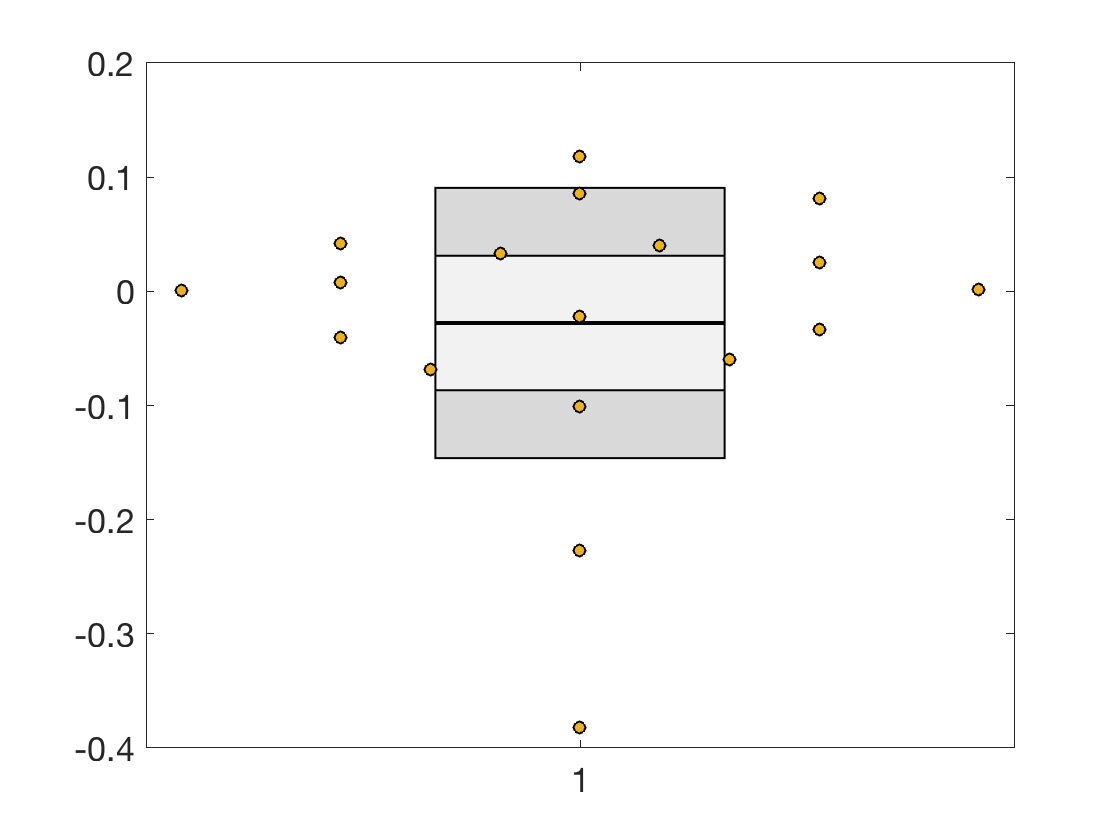


UnivarScatter(rmmissing(lMTG_cluster)')

check the variance in RDS cluster:

ans =     1.1653
    1.1653
    1.2468
    0.7246
    1.0000
    1.0551
    1.1234
    0.8347
    0.8766
    1.0000


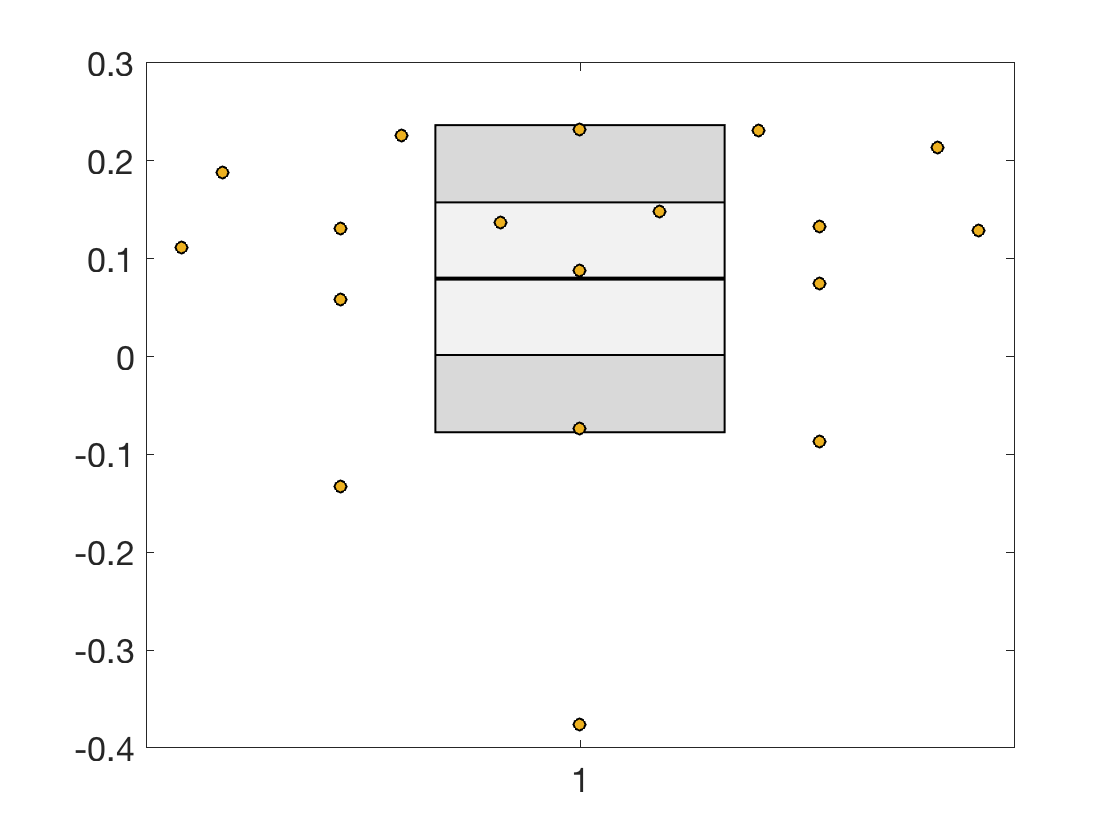

UnivarScatter(rmmissing(PCC_RDS_ROI.Connectivity))